# Preprocessing of Neuropixels recordings in the flight room

- Recording date: 2/7/2024

- Recording method: untethered recording in the flight room.

- Experiment setup: multiple bats (n=10) were flew in the flight room simultaneously. Two bats (14633 and 14662) were recorded for their neural activity.

- Target region of ephys recording: 14633 and 14662 was implanted with two probes respectively. For 14633, the probe 1 was targetting the dorsal/ventral hippocampus and the probe 2 was targetting the mEC. For 14662, the probe 1 was targetting the hippocampus and the mEC and the probe 2 was targetting the dorsal and ventral hippocampus.

- Feeder: feeder 1 and 2 was activated with a banana smoothie syringe.

## Recording information (Edit here)

rec_date = '240208'; % recording date
rec_type = 'untethered'; % recording type
exp_type = 'flight'; % experiment type
data_dir = 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240208'; % parent directory for all recordings
cd(data_dir)

% Bat subjects
bname = {"14447","11827","29924","14406","14561","14633","14662","14531","71050","9776"}; % in order of serial number list
bname_ephys = {'14633','14662'}; % ephys bat

% reward
reward_list = {"banana","pear","grape","melon"};
reward_session = [1,1,0,0; 1,1,0,0];
save('exp_info.mat','rec_date','rec_type','exp_type','bname','bname_ephys','reward_list','reward_session')


### Directory to ouput the results

% output directory
res_dir_path     =   fullfile(data_dir,'analysis');
if isempty(dir(res_dir_path))
    mkdir(res_dir_path)
end
% Figure
fig_dir_path    =   fullfile(res_dir_path,'figure');
if isempty(dir(fig_dir_path))
    mkdir(fig_dir_path)
end

## Preprocessing of Neuropixels data

### Extracting LFP, spikeband, and other data types    

trodes_path = 'C:\Users\Tatsumi\Documents\Trodes\Trodes_2-5-0_Windows64'; % trodes 2.5.0
exportAllTrodesRecordingsAllBats(data_dir,trodes_path,'isTethered',0); % extract LFP, spikeband, kilosort dat, etc. from the raw data for all bats

Extracting data from Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14633 

trodesexport -lfp -analogio -kilosort -dio -spikes -spikeband -time -lfplowpass 500 -lfpoutputrate 1500 -uselfpfilters 0 -spikehighpass 600 -spikelowpass 6000 -usespikefilters 0 -invert 0 -rec "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14633\20240207_103632_merged.rec" -outputdirectory "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14633" -interp 0
Using the following workspace file:  "20240207_103632_merged.trodesconf"
Exporting data...
1.092%2.183%3.275%4.366%5.458%6.549%A gap of 513 packets occured in the file. Last timestamp:  15806085 (Clock is:  "00:08:46" )
A gap of 514 packets occured in the file. Last timestamp:  15811550 (Clock is:  "00:08:47" )
A gap of 514 packets occured in the file. Last timestamp:  15817016 (Clock is:  "00:08:47" )
A gap of 515 packets occured in the file.

chanmap_file = struct with fields:
       name: '20240207_103632_merged.channelmap_probe1.dat'
     folder: 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14633\20240207_103632_merged.kilosort'
       date: '10-Feb-2024 02:31:18'
      bytes: 5253
      isdir: 0
    datenum: 7.3929e+05


Extracting data from Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14662 

trodesexport -lfp -analogio -kilosort -dio -spikes -spikeband -time -lfplowpass 500 -lfpoutputrate 1500 -uselfpfilters 0 -spikehighpass 600 -spikelowpass 6000 -usespikefilters 0 -invert 0 -rec "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14662\20240207_103632_merged.rec" -outputdirectory "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14662" -interp 0
Using the following workspace file:  "20240207_103632_merged.trodesconf"
Exporting data...
A gap of 282 packets occured in the file. Last timestamp:  5216867 (Clock is:  "00:02:53" )
1.085%2.17%3.255%A gap of 4 packets occured in the file. Last timestamp:  10306457 (Clock is:  "00:05:43" )
A gap of 169 packets occured in the file. Last timestamp:  10708103 (Clock is:  "00:05:56" )
4.339%A gap of 45 packets occured in the file. Last timestamp: 

chanmap_file = struct with fields:
       name: '20240207_103632_merged.channelmap_probe1.dat'
     folder: 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14662\20240207_103632_merged.kilosort'
       date: '10-Feb-2024 04:36:02'
      bytes: 2757
      isdir: 0
    datenum: 7.3929e+05


chanmap_file = struct with fields:
       name: '20240207_103632_merged.channelmap_probe2.dat'
     folder: 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14662\20240207_103632_merged.kilosort'
       date: '10-Feb-2024 04:36:02'
      bytes: 3333
      isdir: 0
    datenum: 7.3929e+05


### Run kilosort

% 14633
path_to_rec_dir = 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240208\ephys\20240208_132817.rec\14633'

path_to_rec_dir = 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240208\ephys\20240208_132817.rec\14633'

probeNum = 1;
numChannels = 384;
runKilosort3(path_to_rec_dir,'probeNum',probeNum,'numChannels',numChannels)

Looking for data inside Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240208\ephys\20240208_132817.rec\14633\20240208_132817_merged.kilosort 


errString = 'kilosort repo not found, or inaccessible.'

Time   0s. Computing whitening matrix.. 
Getting channel whitening matrix... 
Channel-whitening matrix computed. 
Time  19s. Loading raw data and applying filters... 
Time 519s. Finished preprocessing 1148 batches. 
vertical pitch size is 20 
horizontal pitch size is 16 
   -24   -16    -8     0     8    16    24

        1534

0.44 sec, 1 batches, 7773 spikes 
41.47 sec, 101 batches, 999485 spikes 
84.18 sec, 201 batches, 1997894 spikes 
130.21 sec, 301 batches, 2990191 spikes 
180.30 sec, 401 batches, 3978060 spikes 
232.95 sec, 501 batches, 4965261 spikes 
288.98 sec, 601 batches, 5952299 spikes 
349.43 sec, 701 batches, 6929057 spikes 
412.32 sec, 801 batches, 7899897 spikes 
489.21 sec, 901 batches, 8868829 spikes 
578.72 sec, 1001 batches, 9829730 spikes 
676.70 sec, 1101 batches, 10781421 spikes 
724.94 sec, 1148 batches, 11215286 spikes 


time 1517.82, Shifted up/down 1148 batches. 
1.06 sec, 1 batches, 10000 spikes 
104.25 sec, 101 batches, 1010000 spikes 
207.20 sec, 201 batches, 2010000 spikes 
310.35 sec, 301 batches, 3010000 spikes 
414.08 sec, 401 batches, 4010000 spikes 
519.99 sec, 501 batches, 5010000 spikes 
626.93 sec, 601 batches, 6010000 spikes 
732.65 sec, 701 batches, 7010000 spikes 
840.55 sec, 801 batches, 8010000 spikes 
947.54 sec, 901 batches, 9010000 spikes 
1054.44 sec, 1001 batches, 10010000 spikes 
1162.95 sec, 1101 batches, 11010000 spikes 
1213.19 sec, 1148 batches, 11470990 spikes 
time 0.00, GROUP 1/384, units 0 
time 4.04, GROUP 6/384, units 5 
time 7.87, GROUP 11/384, units 12 
time 12.33, GROUP 16/384, units 23 
time 15.62, GROUP 21/384, units 30 
time 32.76, GROUP 26/384, units 60 
time 38.09, GROUP 31/384, units 70 
time 42.04, GROUP 36/384, units 77 
time 46.45, GROUP 41/384, units 84 
time 49.77, GROUP 46/384, units 91 
time 55.09, GROUP 51/384, units 102 
time 57.24, GROUP 56/384, uni

time 0.00, GROUP 1/384, units 0 
time 0.03, GROUP 6/384, units 0 
time 0.04, GROUP 11/384, units 0 
time 0.06, GROUP 16/384, units 0 
time 0.07, GROUP 21/384, units 0 
time 0.09, GROUP 26/384, units 0 
time 0.10, GROUP 31/384, units 0 
time 0.12, GROUP 36/384, units 0 
time 0.14, GROUP 41/384, units 0 
time 0.16, GROUP 46/384, units 0 
time 0.18, GROUP 51/384, units 0 
time 0.19, GROUP 56/384, units 0 
time 0.21, GROUP 61/384, units 0 
time 0.22, GROUP 66/384, units 0 
time 0.24, GROUP 71/384, units 0 
time 0.26, GROUP 76/384, units 0 
time 0.28, GROUP 81/384, units 0 
time 0.29, GROUP 86/384, units 0 
time 0.31, GROUP 91/384, units 0 
time 0.32, GROUP 96/384, units 0 
time 10.56, GROUP 101/384, units 14 
time 23.62, GROUP 106/384, units 35 
time 28.48, GROUP 111/384, units 42 
time 34.65, GROUP 116/384, units 49 
time 42.42, GROUP 121/384, units 59 
time 51.70, GROUP 126/384, units 70 
time 61.49, GROUP 131/384, units 80 
time 73.98, GROUP 136/384, units 95 
time 90.39, GROUP 141/384,

ans = 143

initialized spike counts
merged 374 into 368 
merged 20 into 18 
merged 123 into 114 
merged 235 into 240 
merged 375 into 368 
merged 265 into 269 
merged 85 into 87 
merged 276 into 268 
merged 266 into 269 
merged 24 into 28 
merged 272 into 255 
merged 114 into 111 
merged 260 into 254 
merged 255 into 268 
merged 83 into 87 
merged 170 into 175 
merged 118 into 108 
merged 341 into 343 
merged 186 into 190 
merged 131 into 127 
merged 250 into 252 
merged 369 into 376 
merged 419 into 423 
merged 398 into 400 
merged 333 into 329 
merged 278 into 271 


ans = 124

ans = struct with fields:
                ops: [1×1 struct]
                 xc: [384×1 double]
                 yc: [384×1 double]
            xcoords: [384×1 double]
            ycoords: [384×1 double]
               Wrot: [384×384 double]
               temp: [1×1 struct]
              wTEMP: [61×6 single]
               wPCA: [61×6 single]
                 iC: [16×384 gpuArray]
               dist: [10×3452 single]
              iorig: [1148×1 double]
             dshift: [1148×5 double]
                st0: [11215286×6 double]
                  F: [1534×20×1148 double]
                 F0: [1534×20 gpuArray]
                F0m: [1534×20 gpuArray]
               ycup: [100 100 100 100 100 110 110 110 110 110 120 120 120 130 130 130 130 130 140 140 140 140 140 150 150 150 150 150 160 160 160 170 170 170 170 170 180 180 180 180 180 190 190 190 190 190 200 200 200 210 210 210 210 … ] (1×3452 double)
               xcup: [-8 0 8 16 24 -8 0 8 16 24 8 16 24 -8 0 8 16 24 -8 0 8 16 24 -8 


% 14662
path_to_rec_dir = 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240208\ephys\20240208_132817.rec\14662'

path_to_rec_dir = 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240208\ephys\20240208_132817.rec\14662'

probeNum = 1;
numChannels = 188;
runKilosort3(path_to_rec_dir,'probeNum',probeNum,'numChannels',numChannels)

Looking for data inside Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240208\ephys\20240208_132817.rec\14662\20240208_132817_merged.kilosort 


errString = 'kilosort repo not found, or inaccessible.'

Time   0s. Computing whitening matrix.. 
Getting channel whitening matrix... 
Channel-whitening matrix computed. 
Time  13s. Loading raw data and applying filters... 
Time 356s. Finished preprocessing 1148 batches. 
vertical pitch size is 20 
horizontal pitch size is 16 
   -24   -16    -8     0     8    16    24

        1350

0.23 sec, 1 batches, 3960 spikes 
22.76 sec, 101 batches, 404904 spikes 
46.15 sec, 201 batches, 779494 spikes 
72.01 sec, 301 batches, 1122147 spikes 
99.94 sec, 401 batches, 1429690 spikes 
130.29 sec, 501 batches, 1771942 spikes 
162.87 sec, 601 batches, 2097255 spikes 
197.79 sec, 701 batches, 2403755 spikes 
235.02 sec, 801 batches, 2725010 spikes 
274.54 sec, 901 batches, 3081783 spikes 
316.47 sec, 1001 batches, 3438092 spikes 
360.78 sec, 1101 batches, 3800013 spikes 
382.43 sec, 1148 batches, 3966383 spikes 


time 947.49, Shifted up/down 1148 batches. 
0.44 sec, 1 batches, 7383 spikes 
43.97 sec, 101 batches, 815813 spikes 
87.67 sec, 201 batches, 1683688 spikes 
131.49 sec, 301 batches, 2527256 spikes 
174.82 sec, 401 batches, 3248748 spikes 
218.35 sec, 501 batches, 4099142 spikes 
261.83 sec, 601 batches, 4974344 spikes 
306.02 sec, 701 batches, 5845704 spikes 
349.58 sec, 801 batches, 6778368 spikes 
393.18 sec, 901 batches, 7662028 spikes 
437.65 sec, 1001 batches, 8341925 spikes 
481.16 sec, 1101 batches, 9014262 spikes 
501.75 sec, 1148 batches, 9327945 spikes 
time 0.00, GROUP 1/338, units 0 
time 7.65, GROUP 6/338, units 8 
time 13.31, GROUP 11/338, units 13 
time 17.84, GROUP 16/338, units 20 
time 17.85, GROUP 21/338, units 20 
time 17.85, GROUP 26/338, units 20 
time 17.85, GROUP 31/338, units 20 
time 17.85, GROUP 36/338, units 20 
time 17.85, GROUP 41/338, units 20 
time 21.62, GROUP 46/338, units 31 
time 25.46, GROUP 51/338, units 42 
time 28.98, GROUP 56/338, units 52 
time

time 0.00, GROUP 1/338, units 0 
time 18.51, GROUP 6/338, units 14 
time 28.19, GROUP 11/338, units 20 
time 32.17, GROUP 16/338, units 24 
time 32.19, GROUP 21/338, units 24 
time 32.20, GROUP 26/338, units 24 
time 32.20, GROUP 31/338, units 24 
time 32.21, GROUP 36/338, units 24 
time 32.22, GROUP 41/338, units 24 
time 36.04, GROUP 46/338, units 38 
time 39.96, GROUP 51/338, units 49 
time 45.11, GROUP 56/338, units 63 
time 51.59, GROUP 61/338, units 82 
time 57.11, GROUP 66/338, units 96 
time 64.12, GROUP 71/338, units 113 
time 68.76, GROUP 76/338, units 124 
time 75.06, GROUP 81/338, units 139 
time 81.00, GROUP 86/338, units 150 
time 86.09, GROUP 91/338, units 161 
time 95.03, GROUP 96/338, units 181 
time 99.17, GROUP 101/338, units 190 
time 99.18, GROUP 106/338, units 190 
time 99.19, GROUP 111/338, units 190 
time 99.20, GROUP 116/338, units 190 
time 99.20, GROUP 121/338, units 190 
time 99.21, GROUP 126/338, units 190 
time 99.22, GROUP 131/338, units 190 
time 99.22, 

ans = 52

initialized spike counts
merged 269 into 273 
merged 278 into 284 
merged 229 into 232 
merged 200 into 195 
merged 239 into 238 
merged 168 into 171 
merged 221 into 224 
merged 256 into 260 
merged 4 into 1 


ans = 46

ans = struct with fields:
                ops: [1×1 struct]
                 xc: [188×1 double]
                 yc: [188×1 double]
            xcoords: [188×1 double]
            ycoords: [188×1 double]
               Wrot: [188×188 double]
               temp: [1×1 struct]
              wTEMP: [61×6 single]
               wPCA: [61×6 single]
                 iC: [16×188 gpuArray]
               dist: [10×1698 single]
              iorig: [1148×1 double]
             dshift: [1148×5 double]
                st0: [3966383×6 double]
                  F: [1350×20×1148 double]
                 F0: [1350×20 gpuArray]
                F0m: [1350×20 gpuArray]
               ycup: [100 100 100 110 110 110 110 110 120 120 120 120 120 130 130 130 130 130 140 140 140 150 150 150 150 150 160 160 160 160 160 170 170 170 170 170 180 180 180 190 190 190 190 190 200 200 200 200 200 210 210 210 210 … ] (1×1698 double)
               xcup: [-24 -16 -8 -24 -16 -8 0 8 -24 -16 -8 0 8 -24 -16 -8 0 8 -24 -16 


probeNum = 2;
numChannels = 212;
runKilosort3(path_to_rec_dir,'probeNum',probeNum,'numChannels',numChannels)

Looking for data inside Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240208\ephys\20240208_132817.rec\14662\20240208_132817_merged.kilosort 


errString = 'kilosort repo not found, or inaccessible.'

Time   0s. Computing whitening matrix.. 
Getting channel whitening matrix... 
Channel-whitening matrix computed. 
Time  16s. Loading raw data and applying filters... 
Time 403s. Finished preprocessing 1148 batches. 
vertical pitch size is 20 
horizontal pitch size is 16 
   -24   -16    -8     0     8    16    24

        1070

0.28 sec, 1 batches, 6884 spikes 
25.16 sec, 101 batches, 776946 spikes 
51.45 sec, 201 batches, 1435728 spikes 
80.42 sec, 301 batches, 2035567 spikes 
111.79 sec, 401 batches, 2601469 spikes 
145.63 sec, 501 batches, 3114283 spikes 
182.36 sec, 601 batches, 3652611 spikes 
221.82 sec, 701 batches, 4119522 spikes 
263.82 sec, 801 batches, 4574789 spikes 
308.59 sec, 901 batches, 5092710 spikes 
355.86 sec, 1001 batches, 5533766 spikes 
405.62 sec, 1101 batches, 5973855 spikes 
429.98 sec, 1148 batches, 6206712 spikes 


time 1071.37, Shifted up/down 1148 batches. 
0.51 sec, 1 batches, 10000 spikes 
49.95 sec, 101 batches, 1003593 spikes 
99.15 sec, 201 batches, 1988133 spikes 
148.63 sec, 301 batches, 2982955 spikes 
197.97 sec, 401 batches, 3972242 spikes 
247.24 sec, 501 batches, 4893711 spikes 
297.12 sec, 601 batches, 5816069 spikes 
346.40 sec, 701 batches, 6602253 spikes 
395.88 sec, 801 batches, 7457654 spikes 
446.24 sec, 901 batches, 8397038 spikes 
495.52 sec, 1001 batches, 9190703 spikes 
544.79 sec, 1101 batches, 9922426 spikes 
568.14 sec, 1148 batches, 10294036 spikes 
time 0.00, GROUP 1/268, units 0 
time 2.17, GROUP 6/268, units 6 
time 4.60, GROUP 11/268, units 11 
time 13.33, GROUP 16/268, units 28 
time 24.48, GROUP 21/268, units 43 
time 34.38, GROUP 26/268, units 58 
time 39.63, GROUP 31/268, units 67 
time 45.50, GROUP 36/268, units 77 
time 52.78, GROUP 41/268, units 89 
time 57.07, GROUP 46/268, units 96 
time 67.38, GROUP 51/268, units 113 
time 76.43, GROUP 56/268, units 130 

time 0.00, GROUP 1/268, units 0 
time 1.85, GROUP 6/268, units 6 
time 4.42, GROUP 11/268, units 11 
time 12.72, GROUP 16/268, units 25 
time 29.11, GROUP 21/268, units 54 
time 43.42, GROUP 26/268, units 79 
time 50.76, GROUP 31/268, units 93 
time 56.86, GROUP 36/268, units 104 
time 62.53, GROUP 41/268, units 115 
time 66.70, GROUP 46/268, units 122 
time 77.35, GROUP 51/268, units 140 
time 85.90, GROUP 56/268, units 160 
time 91.66, GROUP 61/268, units 169 
time 101.55, GROUP 66/268, units 189 
time 104.20, GROUP 71/268, units 197 
time 104.21, GROUP 76/268, units 197 
time 104.22, GROUP 81/268, units 197 
time 104.22, GROUP 86/268, units 197 
time 104.23, GROUP 91/268, units 197 
time 104.23, GROUP 96/268, units 197 
time 104.24, GROUP 101/268, units 197 
time 104.25, GROUP 106/268, units 197 
time 104.25, GROUP 111/268, units 197 
time 104.26, GROUP 116/268, units 197 
time 104.26, GROUP 121/268, units 197 
time 104.27, GROUP 126/268, units 197 
time 104.28, GROUP 131/268, units

ans = 138

initialized spike counts
merged 16 into 13 
merged 255 into 269 
merged 256 into 269 
merged 333 into 330 
merged 245 into 247 
merged 258 into 269 
merged 335 into 336 
merged 254 into 269 
merged 15 into 13 
merged 217 into 212 
merged 30 into 38 
merged 355 into 361 
merged 306 into 312 
merged 303 into 313 
merged 113 into 116 
merged 13 into 20 
merged 91 into 94 
merged 18 into 22 
merged 152 into 150 
merged 125 into 130 
merged 291 into 302 
merged 82 into 80 
merged 161 into 163 


ans = 119

ans = struct with fields:
                ops: [1×1 struct]
                 xc: [212×1 double]
                 yc: [212×1 double]
            xcoords: [212×1 double]
            ycoords: [212×1 double]
               Wrot: [212×212 double]
               temp: [1×1 struct]
              wTEMP: [61×6 single]
               wPCA: [61×6 single]
                 iC: [16×212 gpuArray]
               dist: [10×1911 single]
              iorig: [1148×1 double]
             dshift: [1148×5 double]
                st0: [6206712×6 double]
                  F: [1070×20×1148 double]
                 F0: [1070×20 gpuArray]
                F0m: [1070×20 gpuArray]
               ycup: [1260 1260 1260 1270 1270 1270 1270 1270 1280 1280 1280 1280 1280 1290 1290 1290 1290 1290 1300 1300 1300 1310 1310 1310 1310 1310 1320 1320 1320 1320 1320 1330 1330 1330 1330 1330 1340 1340 1340 1350 1350 1350 … ] (1×1911 double)
               xcup: [-24 -16 -8 -24 -16 -8 0 8 -24 -16 -8 0 8 -24 -16 -8 0 8 -24 -16 -8


disp('kilosort finished!')

kilosort finished!


## Preprocessing of cdp data

### Data directory

% cdp
cdp_dir = dir(fullfile(data_dir,'cdp','*cdp*.txt')); cdp_path = fullfile(cdp_dir.folder,cdp_dir.name);
% serial number
serial_dir = dir(fullfile(data_dir,'*Serial_numbers*')); serial_path = fullfile(serial_dir.folder,serial_dir.name);
% cortex
cortex_dir  =   dir(fullfile(data_dir,'cortex','*c3d'));
cortex_file =   fullfile(cortex_dir.folder,cortex_dir.name);
% reward
reward_dir  =   dir(fullfile(data_dir,'reward','*.mat'));

% experiment info
load('exp_info.mat')
n_session = size(reward_session,1);
reward_summary = cell(n_session,4);
for i = 1:n_session
    for fd = 1:4
        fl = reward_session(i,fd);
        if fl ~= 0
            reward_summary{i,fd} = reward_list{fl};
        end
    end
end
reward_summary

reward_summary = 1×4 cell array
    {'banana'}    {'banana'}    {0×0 double}    {0×0 double}


### Preprocess the cdp data

Extract the tag data from the raw cdp data by the *ExtractCdp* function. *sync_data(:,8)* is the timestamps interpolated based on the pseudo-Fibonacci TTLs. In this time vector, t=0 is the timing of the 1st pulse of the pseudo-Fibonacci TTLs. Make sure that this time vector will be shifted for 1.05 sec to set t=0 as the 1st pulse of the 3-sec TTLs.

                 Fs: 100
             tag_SN: [10×1 double]
            sync_SN: 17040920
               sync: 1
      sync_duration: 28.5297
       sync_samples: 171171
       tag_duration: [28.5304 28.5304 28.5304 28.5304 28.5304 28.5304 28.5304 28.5304 28.5306 28.5304]
        tag_samples: [170306 170252 170354 170276 170291 154435 170314 162235 170214 170279]
    tag_ac_duration: [28.5305 28.5304 28.5303 28.5304 28.5304 28.5304 28.5305 28.5305 28.5304 28.5304]
     tag_ac_samples: [170289 170309 172164 171475 172088 155443 172799 163493 172589 171176]
               tags: 10

All TTLs were detected, alignment OK
Sync: Fs (network time VS interpolated): 100Hz VS 98.12 Hz
Pos Tag1: Fs (network time VS interpolated): 99.49 Hz VS 97.63 Hz


Pos Tag2: Fs (network time VS interpolated): 99.46 Hz VS 97.6 Hz


Pos Tag3: Fs (network time VS interpolated): 99.52 Hz VS 97.65 Hz


Pos Tag4: Fs (network time VS interpolated): 99.47 Hz VS 97.61 Hz


Pos Tag5: Fs (network time VS interpolated): 99.48 Hz VS 97.62 Hz


Pos Tag6: Fs (network time VS interpolated): 90.22 Hz VS 88.53 Hz


Pos Tag7: Fs (network time VS interpolated): 99.49 Hz VS 97.63 Hz


Pos Tag8: Fs (network time VS interpolated): 94.77 Hz VS 93 Hz


Pos Tag9: Fs (network time VS interpolated): 99.43 Hz VS 97.57 Hz


Pos Tag10: Fs (network time VS interpolated): 99.47 Hz VS 97.61 Hz


Acc Tag1: Fs (network time VS interpolated): 99.48 Hz VS 97.62 Hz
Acc Tag2: Fs (network time VS interpolated): 99.49 Hz VS 97.63 Hz
Acc Tag3: Fs (network time VS interpolated): 100.6 Hz VS 98.69 Hz
Acc Tag4: Fs (network time VS interpolated): 100.2 Hz VS 98.3 Hz
Acc Tag5: Fs (network time VS interpolated): 100.5 Hz VS 98.65 Hz
Acc Tag6: Fs (network time VS interpolated): 90.8 Hz VS 89.11 Hz
Acc Tag7: Fs (network time VS interpolated): 100.9 Hz VS 99.06 Hz
Acc Tag8: Fs (network time VS interpolated): 95.51 Hz VS 93.72 Hz
Acc Tag9: Fs (network time VS interpolated): 100.8 Hz VS 98.94 Hz
Acc Tag10: Fs (network time VS interpolated): 100 Hz VS 98.13 Hz


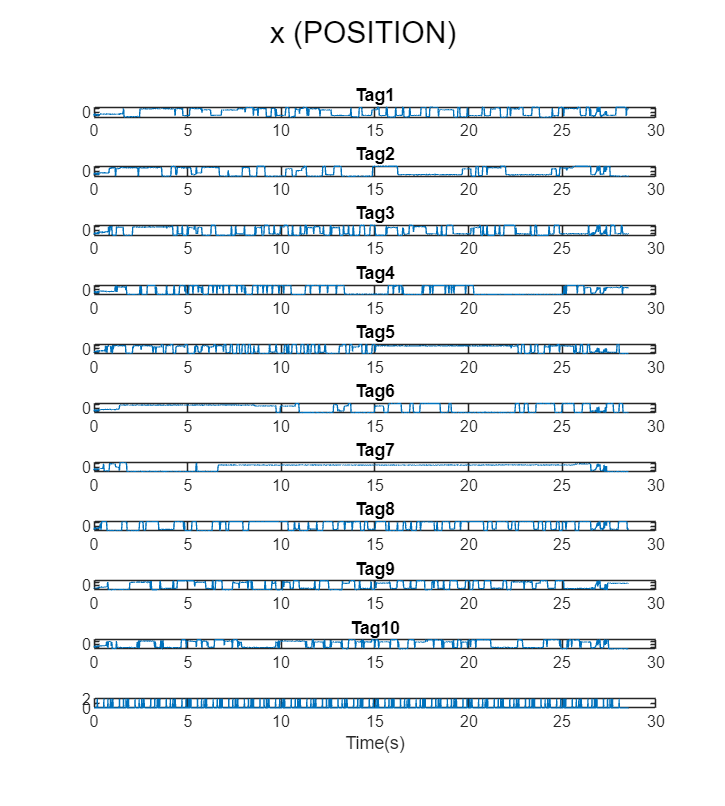

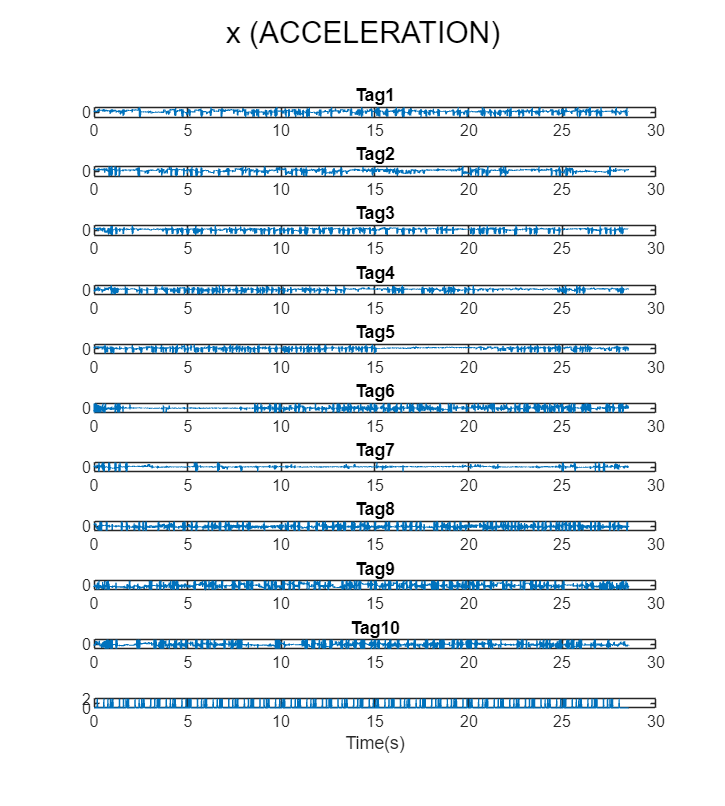

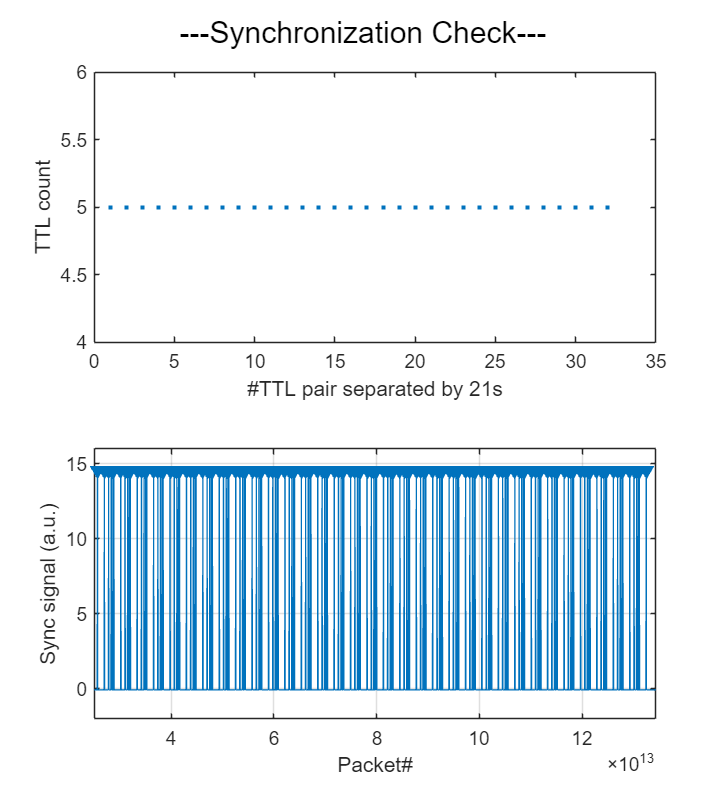

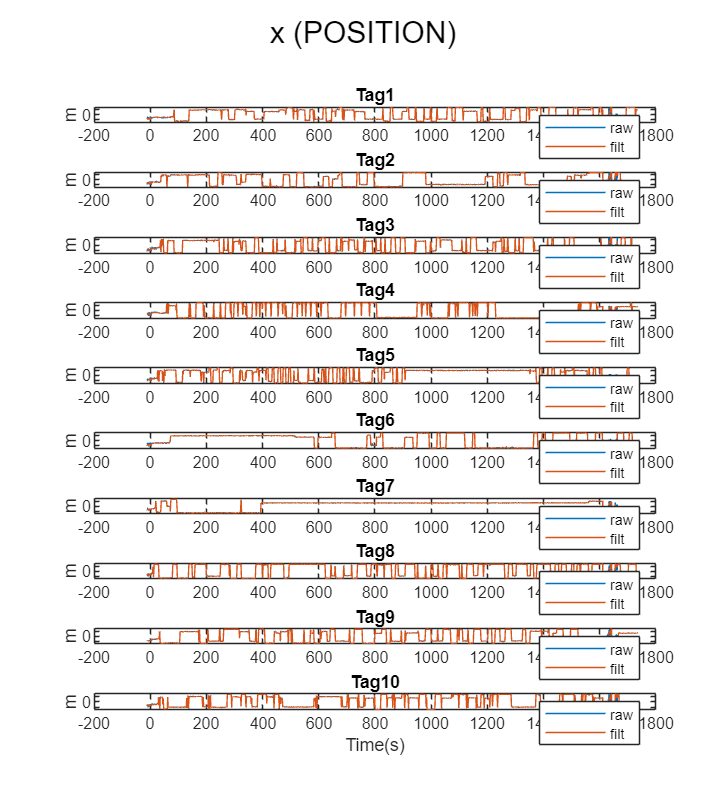

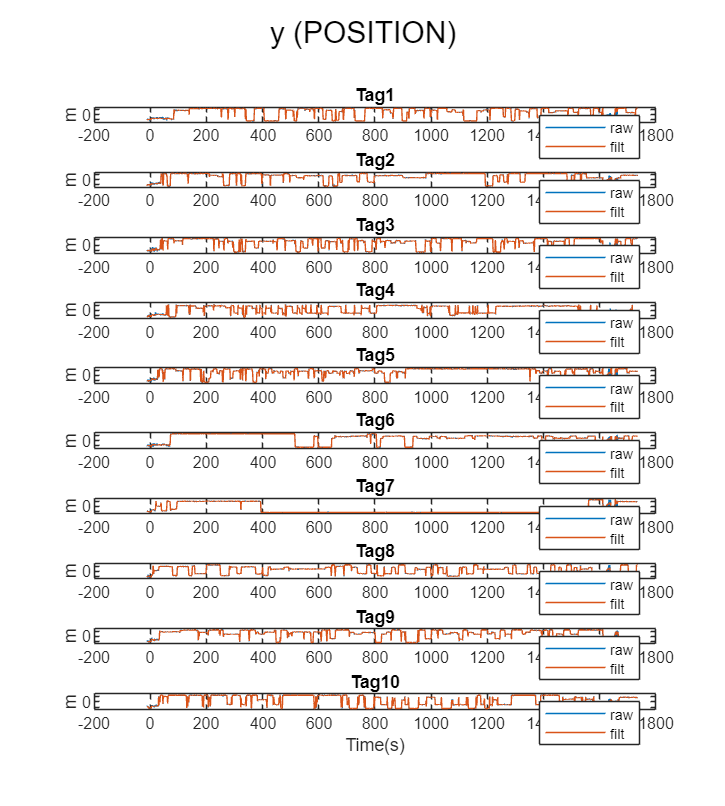

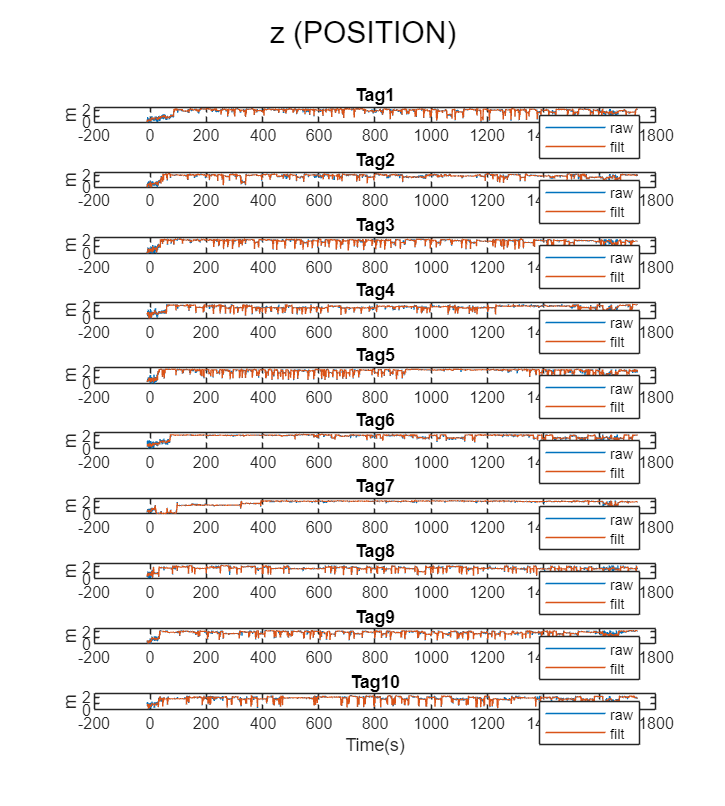

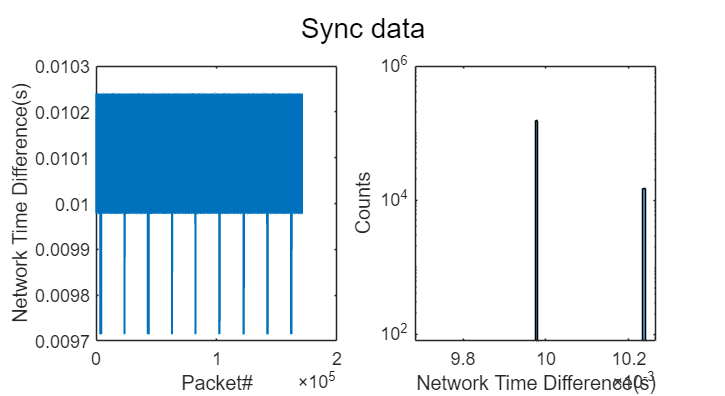

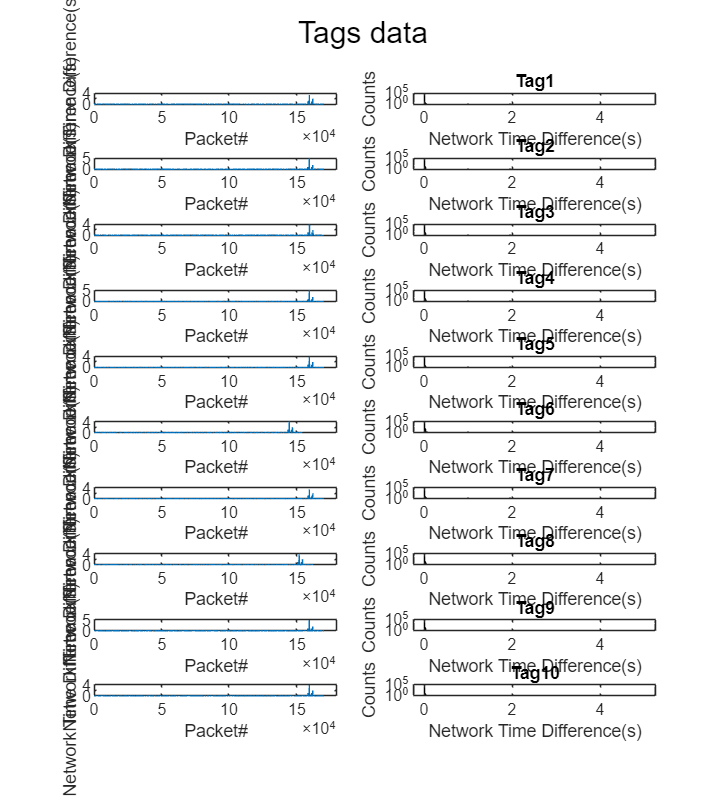

% Preprocess raw cdp data
cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*')); % raw cdp data
serial_number   =   load(serial_path); serial_number   =   serial_number'; % serial number of tags
if isempty(cdp_extracted)
    cd(cdp_dir.folder)
    ExtractCdp_AF_TY_v2('cdp',res_dir_path,'Include',serial_number) % Extract cdp data keeping the tag order
    cd(data_dir)
    % Load data
    cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*'));
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
elseif length(cdp_extracted) == 1
    disp('Extracted data are found in the directory.')
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
else
    error('Multiple files with the specified name were found. Check the file name.')
end

Output file is *extracted_YYMMDD_cdp_*.mat* under the "analysis" directory.

### Extract behavior data

The *Process_extracted_cdp* function extract behavioral features from the preprocessed data. The output is *Extracted_Behavior_YYMMDD.mat* under the "Ext_Behavior_YYMMDD_HHMM.mat" directory.

The variable *t* in the output file is the time vector for global time. The global time is set so that t=0 is the timing of the 1st 3-sec TTLs.

...Processing Ciholas Data...


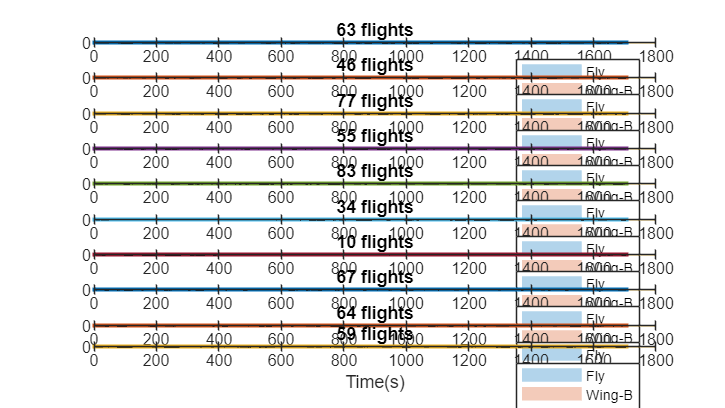

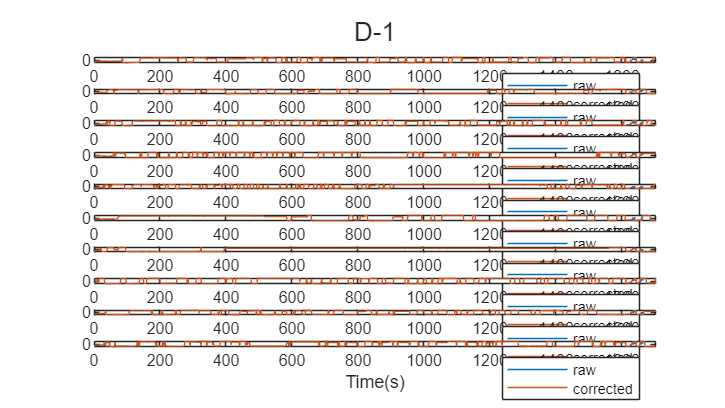

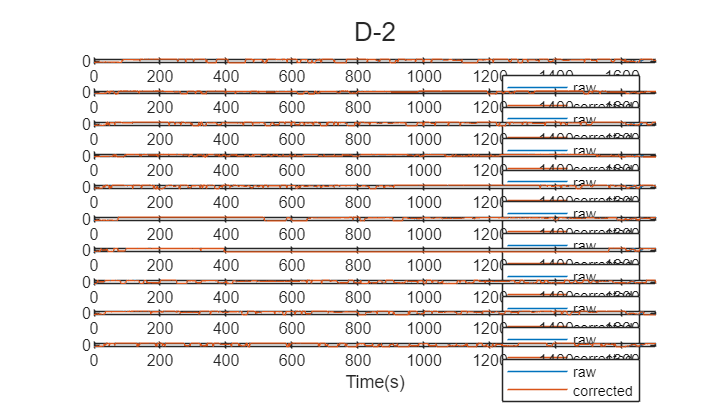

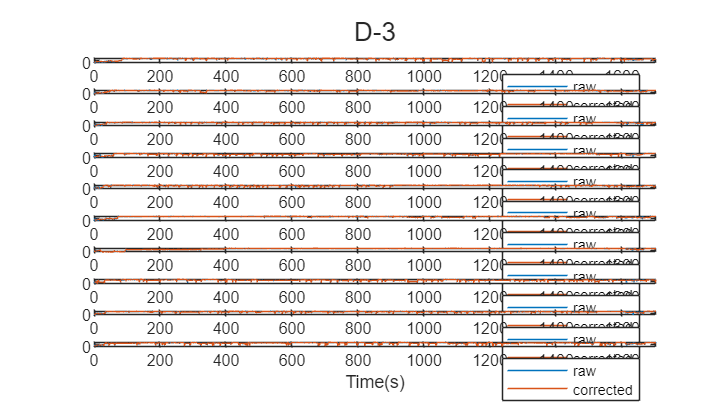

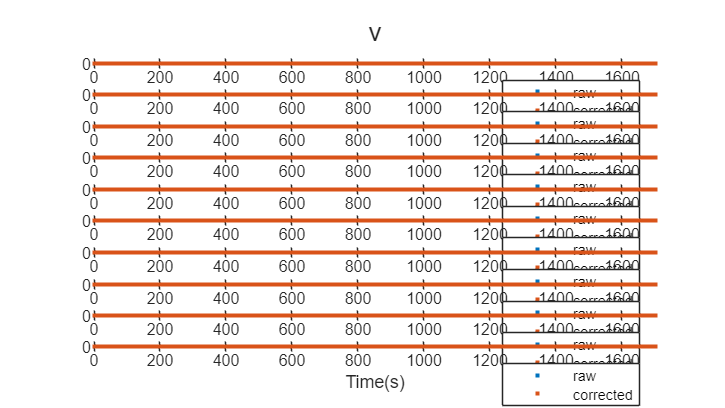

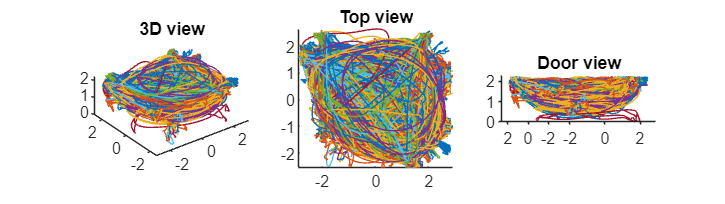

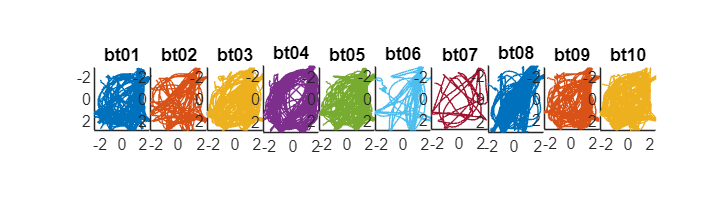

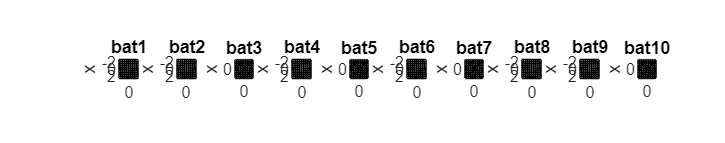

% Extract behaviors
beh_dir             =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
if isempty(beh_dir)
    cd(res_dir_path)
    Process_extracted_cdp_TY_v0(res_dir_path) % Extract behavioral features
    cd(data_dir)
    % Load data
    beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
    load(fullfile(beh_dir.folder,beh_dir.name))
elseif length(cdp_extracted) == 1
    disp('Behavior data are found in the directory.')
    load(fullfile(beh_dir.folder,beh_dir.name))
    disp('Behavior data are loaded.')
else
    error('Multiple files were contained in the directory. Check the file name.')
end

### Extract feeder data

The information related to reward provision is stored in the MATLAB files in the reward directory. These files contain the timings of reward provision, the identity of the bat who landed on feeders, the identity of feeders, etc.

#### Extracting sync signals

Extract the sync and reward information from the c3d file and save them into a MATLAB file.

% Extract synchronization and reward signals from c3d file
analog_dir = dir(fullfile(res_dir_path,'analog_signal.mat'));
if isempty(analog_dir)
    [~,~,AnalogSignals,AnalogFrameRate,~,~,~] = readC3D_analog(cortex_file); % read C3D data. Column 1 = reward, Column 2 = TTL, Column 3 = CDP server
elseif length(analog_dir)==1
    disp('Analog signal data are found.')
    load(fullfile(res_dir_path,'analog_signal.mat'),'AnalogSignals','AnalogFrameRate')
else
    error('Multiple files were contained in the directory. Check the file name.')
end
AnalogSignals = process_analog_signals(AnalogSignals,AnalogFrameRate);